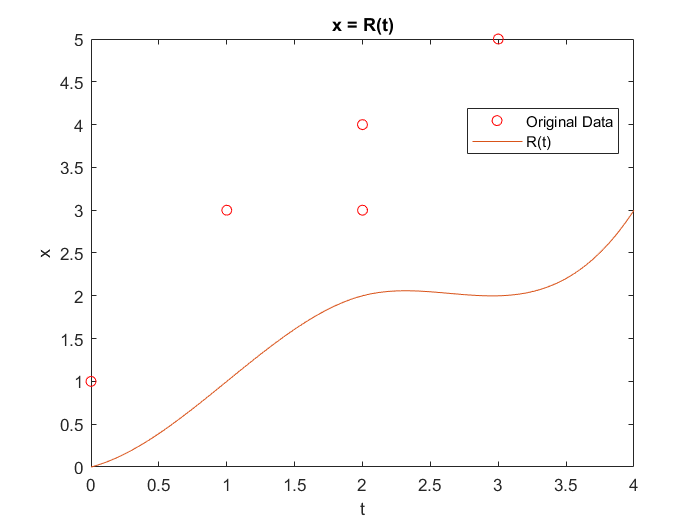

% a)
t = [0 1 2 3 4];
x = [0.0 1.0 2.0 2.0 3.0];
y = [1.0 3.0 3.0 4.0 5.0];
xx = linspace(0, 4, 1000);
grid on
pp1 = spline(t, y);
St = ppval(pp1, xx);
pp2 = spline(t, x);
Rt = ppval(pp2, xx);

plot(x, y, 'ro', xx, Rt)
title 'x = R(t)'
xlabel('t')
ylabel('x')
legend ('Original Data','R(t)', 'location', 'best')

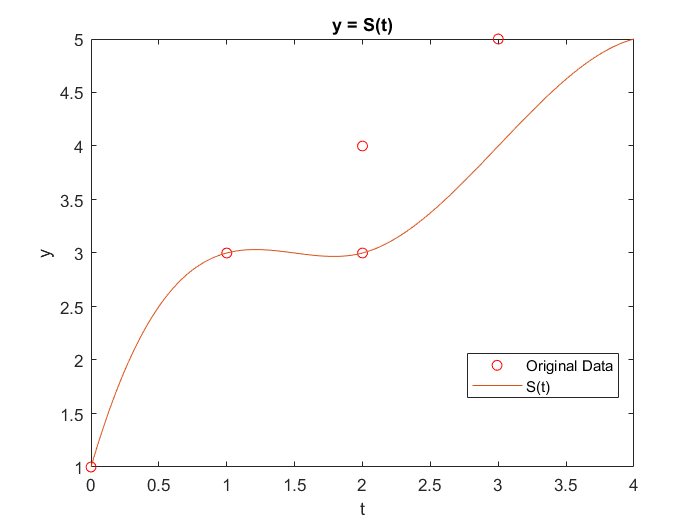


plot(x, y, 'ro', xx, St)
title 'y = S(t)'
xlabel('t')
ylabel('y')
legend ('Original Data','S(t)', 'location', 'best')

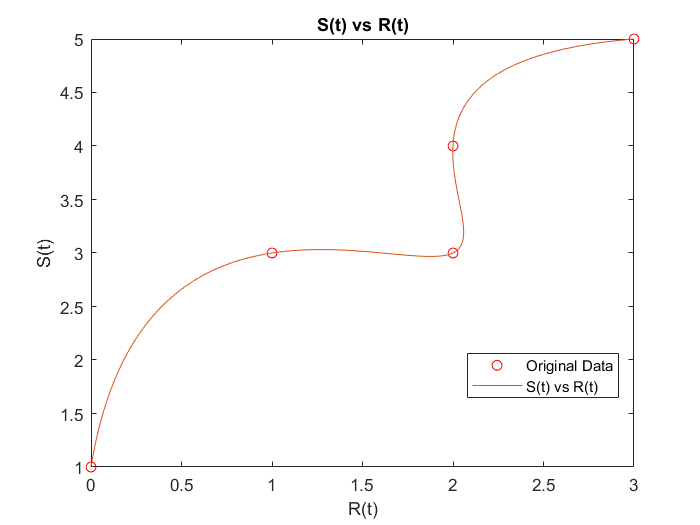


plot(x, y, 'ro', Rt, St)
title  'S(t) vs R(t)'
xlabel('R(t)')
ylabel('S(t)')
legend ('Original Data','S(t) vs R(t)', 'location', 'best')


% b)
x2 = [2.75 1.3 -0.25 0.0 0.25 -1.3 -2.5 -1.3 0.25 0.0 -0.25 1.3 2.75];
y2 = [-1.0 -0.75 0.8 2.0 0.8 -0.25 0.0 0.25 -1.3 -2.5 -1.3 -0.25 -1.0];
t2 = [-3 -2.5 -2 -1.5 -1 -0.5 0 0.5 1 1.5 2 2.5 3];
xx2 = linspace(-3, 3, 1000);

pp3 = spline(t2, x2);
Rt2 = ppval(pp3, xx2)

Rt2 =     2.7500    2.7443    2.7381    2.7316    2.7246    2.7172    2.7094    2.7013    2.6927    2.6838    2.6745    2.6648    2.6548    2.6444    2.6336    2.6225    2.6110    2.5992    2.5870    2.5746    2.5618    2.5486    2.5352    2.5214    2.5073    2.4929    2.4783    2.4633    2.4480    2.4325    2.4166    2.4005    2.3842    2.3675    2.3506    2.3335    2.3161    2.2984    2.2805    2.2624    2.2441    2.2255    2.2067    2.1877    2.1684    2.1490    2.1294    2.1095    2.0895    2.0693


pp4 = spline(t2, y2);
St2 = ppval(pp4, xx2)

St2 =    -1.0000   -1.0094   -1.0185   -1.0272   -1.0355   -1.0435   -1.0512   -1.0585   -1.0654   -1.0720   -1.0783   -1.0842   -1.0898   -1.0951   -1.1000   -1.1046   -1.1088   -1.1128   -1.1164   -1.1197   -1.1226   -1.1253   -1.1276   -1.1296   -1.1313   -1.1327   -1.1338   -1.1346   -1.1350   -1.1352   -1.1351   -1.1347   -1.1339   -1.1329   -1.1316   -1.1300   -1.1281   -1.1260   -1.1235   -1.1208   -1.1178   -1.1145   -1.1109   -1.1071   -1.1029   -1.0986   -1.0939   -1.0890   -1.0838   -1.0784


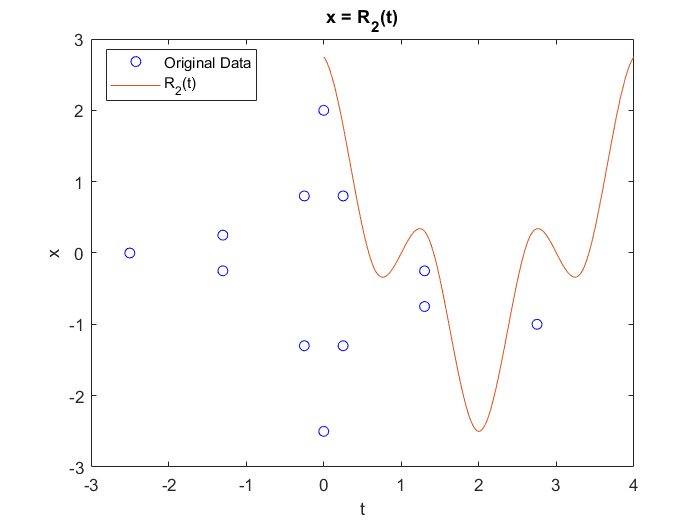


plot(x2, y2, 'bo', xx, Rt2)
title  'x = R_2(t)'
xlabel('t')
ylabel('x')
legend ('Original Data','R_2(t)', 'location', 'best')

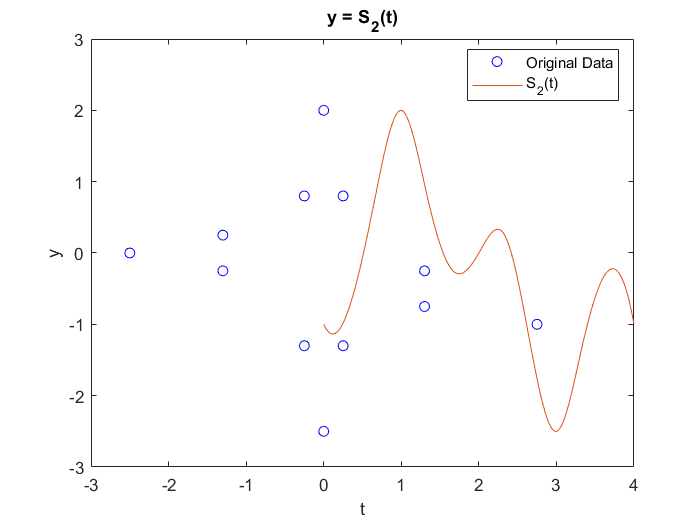


plot(x2, y2, 'bo', xx, St2)
title  'y = S_2(t)'
xlabel('t')
ylabel('y')
legend ('Original Data','S_2(t)', 'location', 'best')

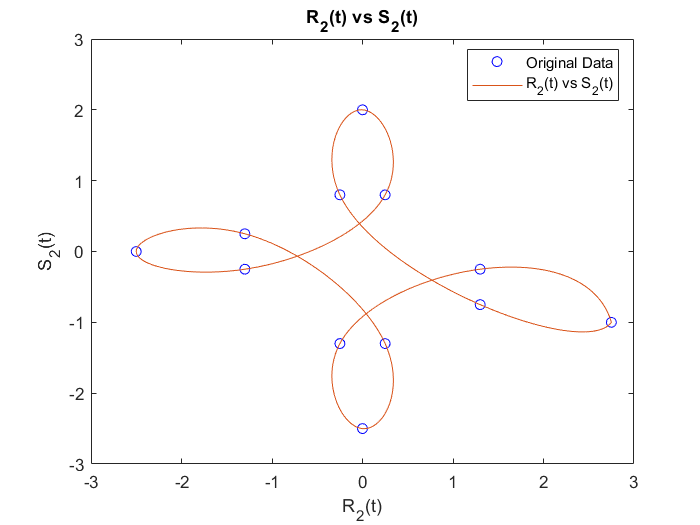


plot(x2, y2, 'bo', Rt2, St2)
title  'R_2(t) vs S_2(t)'
xlabel('R_2(t)')
ylabel('S_2(t)')
legend ('Original Data','R_2(t) vs S_2(t)', 'location', 'best')

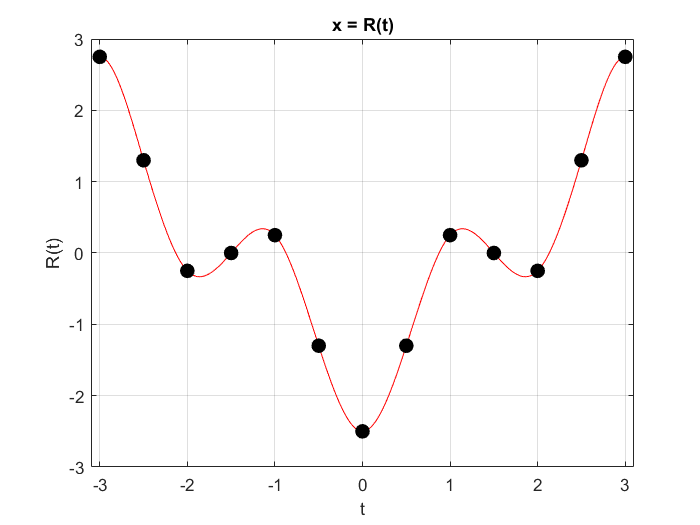


% c)
[ylist1] = perspline(t2, x2, 1);

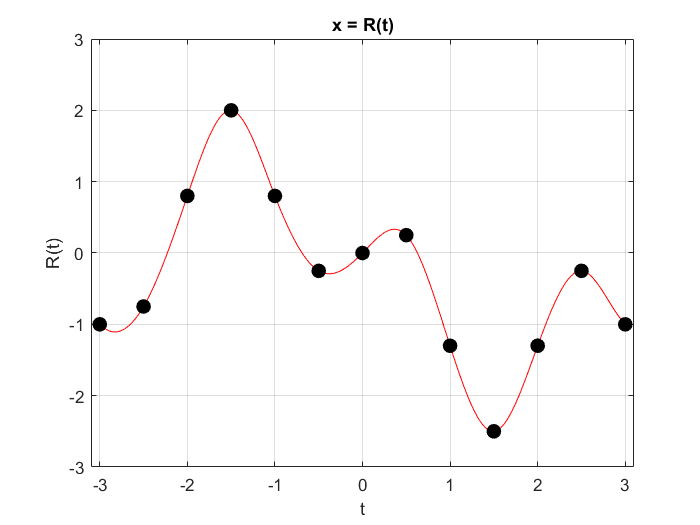

[ylist2] = perspline(t2, y2, 1);

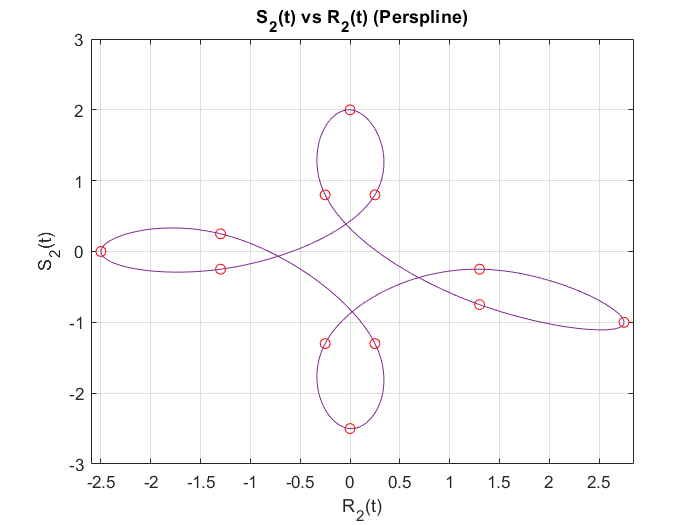

[ylist3] = perspline(ylist1, ylist2, 0);


% d)
%figure('position', get(0,'screensize')) % biggest window possible
%axes('position', [0 0 1 1]) % domain [0,1] x [0,1]
%axis square % x,y axes equal
%[x,y] = ginput; % record mouse clicks
%close % get rid of huge window
%save mydatafile.mat x y % save the data points
% I renamed the variables x and y to xd and yd in the variable editor
%td = linspace(0, 1, length(xd))
%[ylist4] = perspline(td, xd', 1);
%[ylist5] = perspline(td, yd', 1);
%[ylist6] = perspline(ylist4, ylist5, 0);